## Wafers production Company

a factory produces wafers.

- **Dataset:** wafers.txt contains data about produced wafers with 3 proportions (**Thickness**, **Length**, and **Width**). 

- To use the dataset, you need to install **FSDA** toolbox.

**Load** and **transform** data 

T = readtable('wafer.txt');
X = table2array(T);

% count of wafers
[n, p] = size(X);

% Row names
rnames = "w" + (1:n);
T.Properties.RowNames = rnames; % set row names to table
cnames = T.Properties.VariableNames; % column names

Display few rows of the table

disp(head(T, 5))

          Thickness    Length    Width
          _________    ______    _____

    w1        7          4         3  
    w2        4          1         8  
    w3        6          3         5  
    w4        8          6         1  
    w5        8          5         7  



**Plot** measurements to identify anomalous wafers.

### **Parallel Coordinates plot**

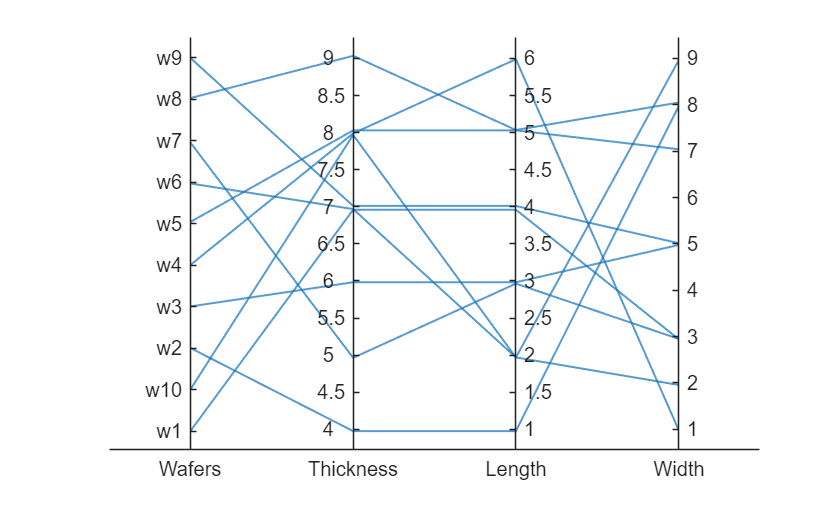

Tt = addvars(T, rnames', 'Before', 1, 'NewVariableNames', 'Wafers');
hold off; % just to prevent frequent errors
parallelplot(Tt);

**My thoughts:**

However, the plot does not tell a lot about data, but I can see a wafer does not comply with the prescribed proportions. Because, **2 wafers** (1 and 9) have same **Thinkness** and **Length** but different **Widths**. I think, it should not be like this.

### Scatterplot Matrix with Univariate boxplot

% relationship among proportions and correlation matrix
Z = zscore(X);
R = cov(Z);

% Display the correlation matrix (table format)
Rt = array2table(R, "RowNames",cnames, "VariableNames",cnames);
disp(Rt);

                 Thickness     Length      Width  
                 _________    ________    ________

    Thickness           1      0.66866    -0.10131
    Length        0.66866            1    -0.28793
    Width        -0.10131     -0.28793           1



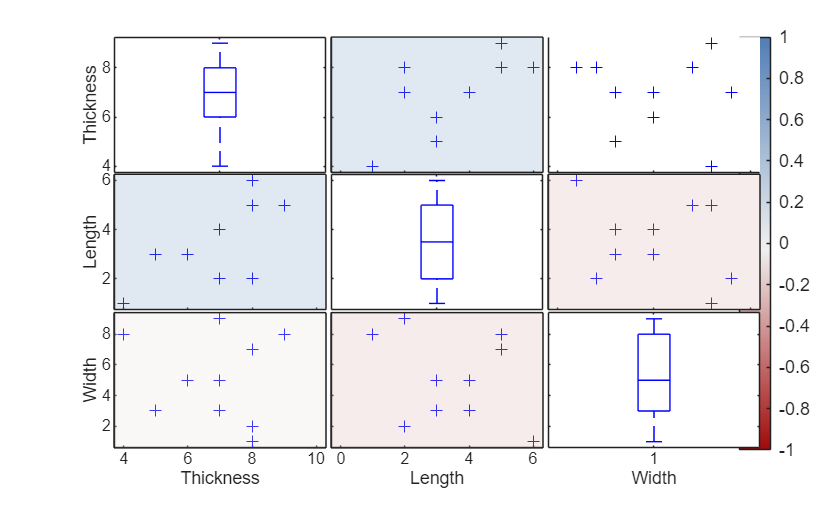


% scatter plot matrix
spmplot(T, "colorBackground",true, "dispopt","box");

**My thoughts**

**No**, propertions among some wafers are not fixed. Because, if it was fixed, then all correlations between variables would be exactly 1 or -1. Also, by creating a **scatter plot** of any two variables would form a perfectly straight line with no outliers.

### Dimensionality Reduction

Using principal component analysis (pca).

[coeff, score, lasor, ~, pctExplained] = pca(Z); % principal component scores

**Summary Matrix**

Autoval = [lasor, pctExplained, 100*cumsum(lasor)/p];

namecols = {'Eigenvalue', 'PctExplained', 'CumPct'};
namePCs = "PC" + (1:p)';
Autovaltbl = array2table(Autoval, 'RowNames', namePCs, 'VariableNames',namecols);
disp(Autovaltbl)

           Eigenvalue    PctExplained    CumPct
           __________    ____________    ______

    PC1      1.7688         58.959       58.959
    PC2     0.92708         30.903       89.862
    PC3     0.30415         10.138          100



**Plotting PCs**

with Pareto plot with each PC's variance.

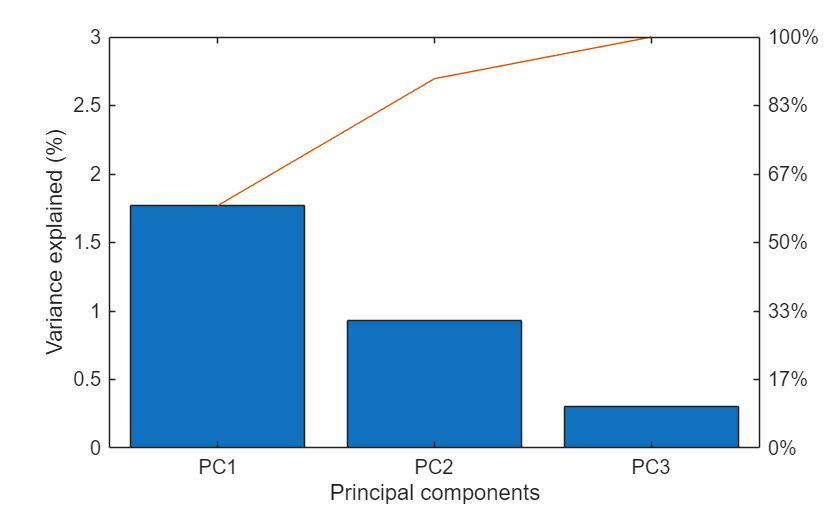

figure
pareto(Autoval(:, 1), namePCs);
xlabel('Principal components')
ylabel('Variance explained (%)')

k = 2; % appropriate number of PCs

Loadings = -coeff * sqrt(diag(lasor));

% Sum of squared correlations of each column of loadings matrix
j = 1;
disp(['Sum of squares of column ' num2str(j) '=' num2str(sum(Loadings(:,j).^2))])

Sum of squares of column 1=1.7688


disp(['Eigenvalue ' num2str(j) ' = ' num2str(lasor(j))])

Eigenvalue 1 = 1.7688


**Graphical representation** of the correlations

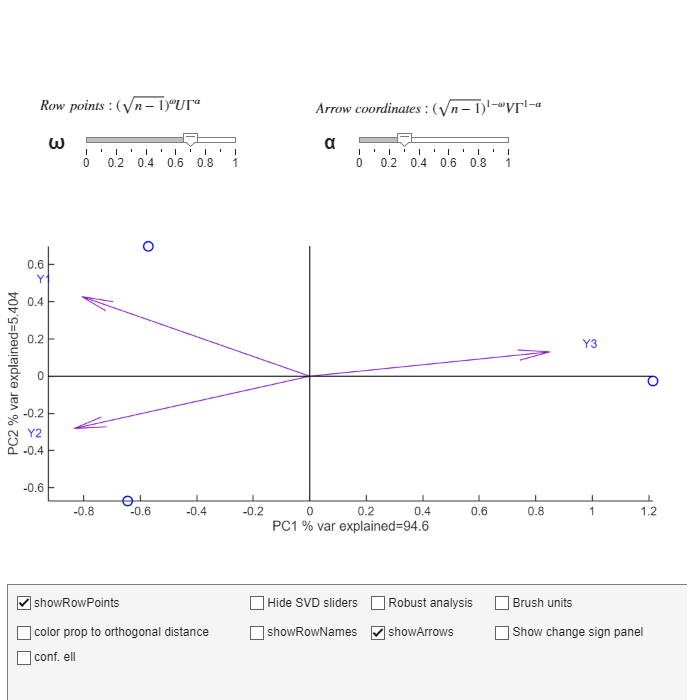

biplotAPP(R); % fix needed